clear all;
close all;
clc;
%Oceanside buoy correlation
%start time is July 10 2020 17:00:00
startTime = 20200710170000;
%end time is July 16 2020 00:00:00
endTime = 20200716000000;
%load glider data
gliderTable = readtable('metbuoy_19-04.csv');
%get waveglider time and wind vectors for appropriate times
[wgt wgWind10m ~] = gliderTime(gliderTable, startTime, endTime);
%upload san nic band frequency table
freqTable = readtable('Oceanside_July2020.txt');

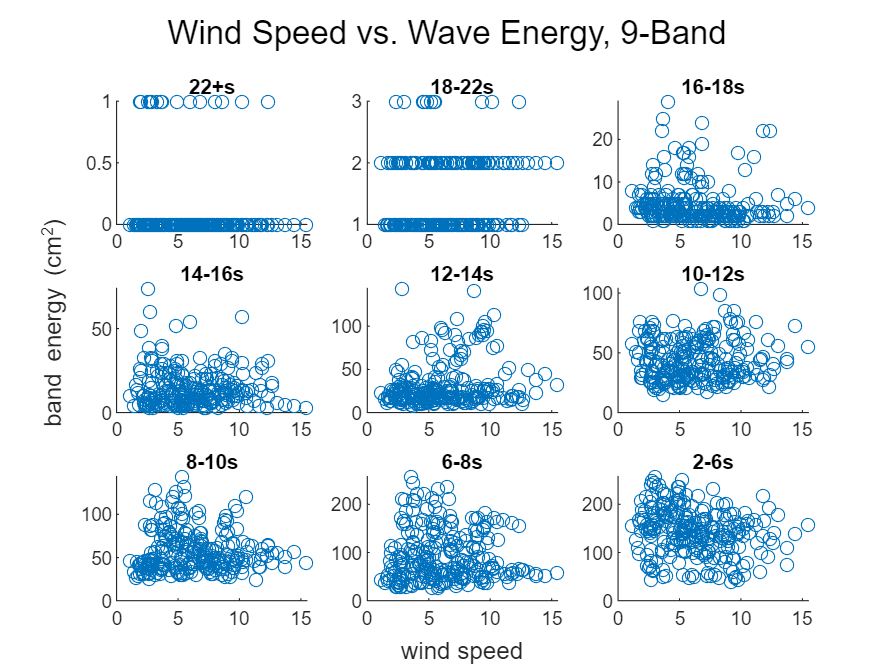

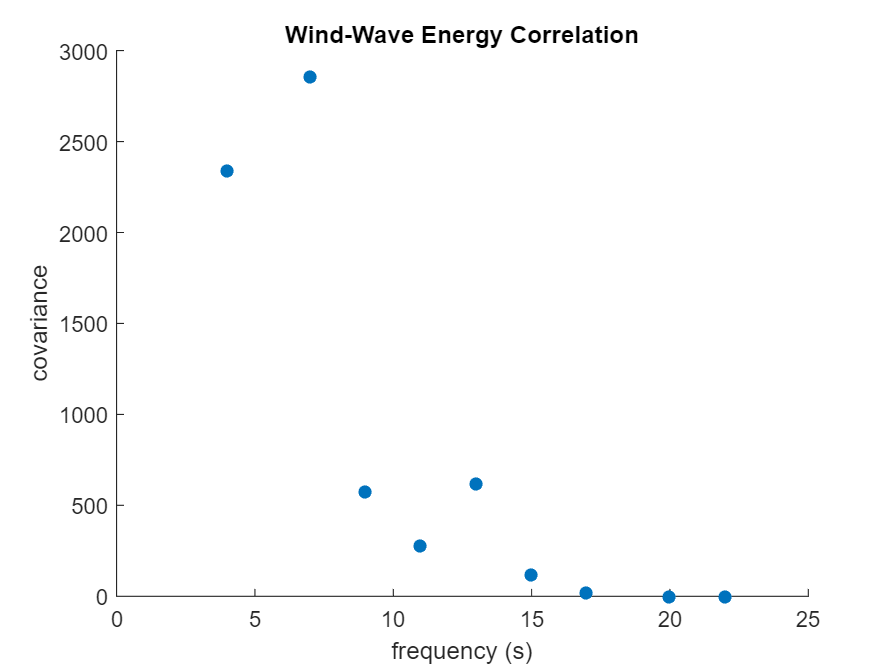

%correlation
windWaveCorr(freqTable, startTime, endTime, wgt, wgWind10m)